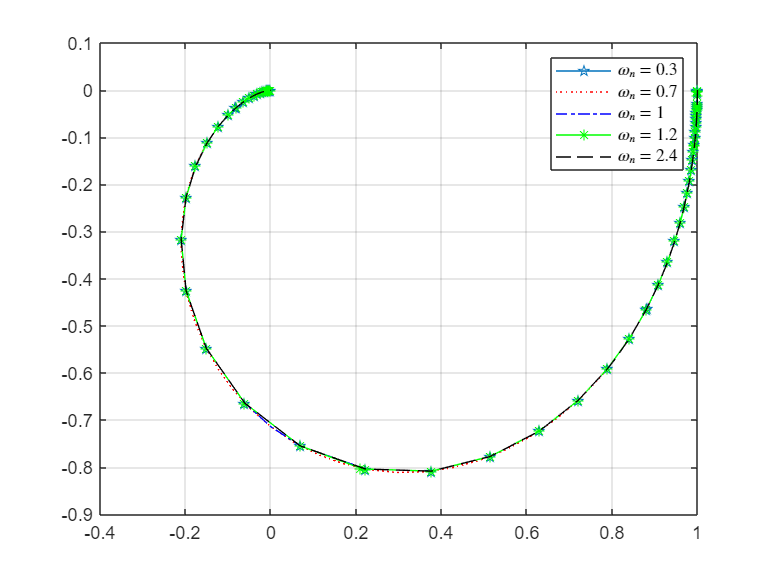

clear all;
close all;
clc


s = tf('s');

wn =0.3; eta=0.7;
P1 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
[re1,im1,w1]=nyquist(P1);

wn =0.7; eta=0.7;
P2 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
[re2,im2,w2]=nyquist(P2);

wn =1; eta=0.7;
P3 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
[re3,im3,w3]=nyquist(P3);

wn =1.2; eta=0.7;
P4 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
[re4,im4,w4]=nyquist(P4);

wn =2.4; eta= 0.7;
P5 = wn*wn/(s*s+ 2*eta*s*wn+ wn*wn);
[re5,im5,w5]=nyquist(P5);

figure;
plot(squeeze(re1),squeeze(im1),'p-', ...
     squeeze(re2),squeeze(im2),'r:', ...
     squeeze(re3),squeeze(im3),'b-.',...
     squeeze(re4),squeeze(im4),'g-*',...
     squeeze(re5),squeeze(im5),'black--');
grid on;
hh = legend('$\omega_n = 0.3$','$\omega_n = 0.7$','$\omega_n = 1$','$\omega_n = 1.2$','$\omega_n  = 2.4$');
set(hh,'Interpreter','latex'); 

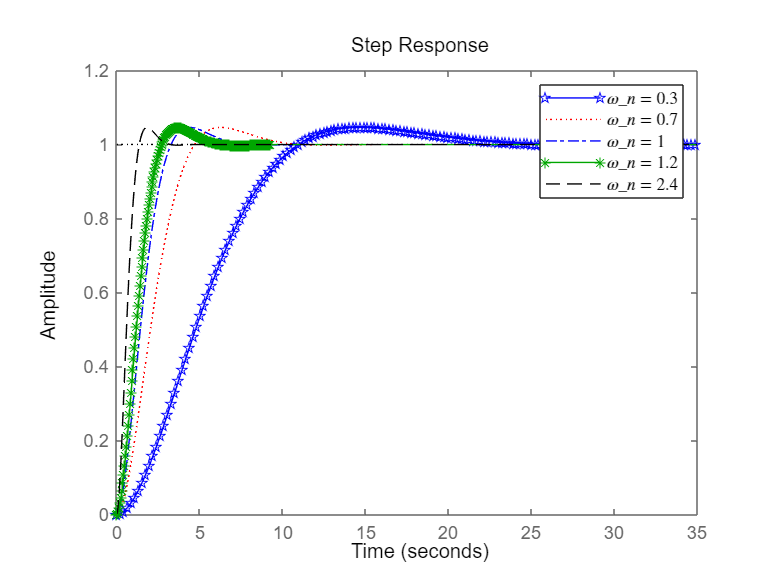


figure;
step(P1,'p-', ...
     P2,'r:', ...
     P3,'b-.',...
     P4,'g-*',...
     P5,'black--');
 
hh = legend('$\omega_n = 0.3$','$\omega_n = 0.7$','$\omega_n = 1$','$\omega_n = 1.2$','$\omega_n  = 2.4$');
set(hh,'Interpreter','latex'); 